# Project 2

In collaboration with: Caleb Rudick, Michael Klein Wassink

## Part 1

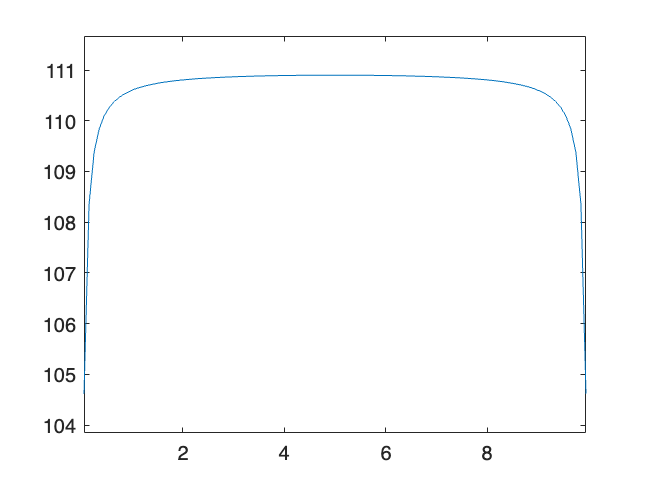

clc
clear 
close all

% initialize parameters
v_inf = 168.8;
c = 1.5;
b = 10;
n = 100;
k = n+1;

% initialize y_trailing and y_bound
y_trail = zeros(k,1);
step = b/n;
for i = 1:k
    y_trail(i) = step*(i-1);
end
y_bound = y_trail(1:n)+(step/2);

% initialize angle of attack of geometry, induced, and effective
alpha_g = 8 * (pi/180) * ones(n,1);
alpha_eff = alpha_g;

% coefficient of lift
Cl = 2 * pi * alpha_eff;

% gamma for a specific boundary
gamma_bn = 0.5 * Cl * v_inf * c;
gamma_bn_new = gamma_bn+1;

% while gamma has not yet converged
% while (gamma_bn(1) - gamma_bn_new(1)) / gamma_bn(1) < 0.0001
while (gamma_bn(1)-gamma_bn_new(1))/gamma_bn(1) < 0.0001
    gamma_tk = zeros(k,1);
    for i = 2:n
        gamma_tk(i) = gamma_bn(i)-gamma_bn(i-1);
    end
    gamma_tk(1) = gamma_bn(1);
    gamma_tk(k) = -gamma_bn(n);
    
    for n=1:n
        for k=1:k
            v_ind(n,k) = -gamma_tk(k)/(4*pi*(y_bound(n)-y_trail(k)));
        end
    end
    
    v_ind_new = sum(v_ind,2); 
    alpha_i = atan(-v_ind_new/v_inf);
    alpha_eff = alpha_g - alpha_i;
    Cl = 2 * pi * alpha_eff;
    gamma_bn_new = 0.5 * Cl * v_inf*c;
    gamma_bn = gamma_bn + 0.01*(gamma_bn_new-gamma_bn); 
end
        
plot(y_bound, gamma_bn);
axis equal

## Part 2

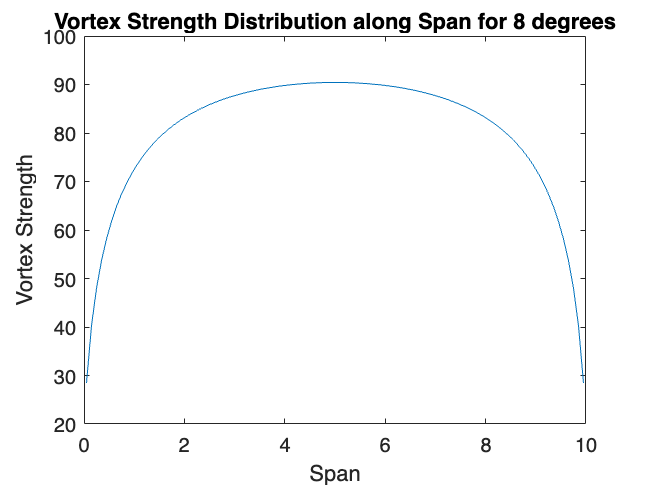

clc
clear
close all
        
% initialize parameters
v_inf = 168.8; 
c = 1.5;
b = 10;
n = 100;
k = n+1;
aoa = 8;

y_trail = zeros(k,1);
step = b/n;
for i = 1:k
    y_trail(i) = step*(i-1);
end
y_bound = y_trail(1:n)+(step/2);

gamma_g = aoa * ones(n,1);
alpha_i = zeros(n,1);
alpha_eff = gamma_g - alpha_i;

load('cl_cd.mat');
Cl = interp1(Cl_0012(:,1),Cl_0012(:,2),alpha_eff,'linear','extrap');
Cd = interp1(Cd_0012(:,1),Cd_0012(:,2),alpha_eff,'linear','extrap');

gamma_bn = 0.5.*Cl*v_inf*c .* (sqrt(1-((y_bound - b/2)/(b/2)).^2));
gamma_bn_new = gamma_bn+1;

% while (mean(gamma_bn)-mean(gamma_bn_new))/mean(gamma_bn) < 0.0001
while (gamma_bn(1)-gamma_bn_new(1))/gamma_bn(1) < 0.0001
    gamma_tk = zeros(k,1);
    for i = 2:n
        gamma_tk(i) = gamma_bn(i)-gamma_bn(i-1);
    end
    gamma_tk(1) = gamma_bn(1);
    gamma_tk(k) = -gamma_bn(n);

    for n=1:n
        for k=1:k
            v_ind(n,k) = -gamma_tk(k)/(4*pi*(y_bound(n)-y_trail(k)));
        end
    end
       
    v_ind_new = sum(v_ind,2);

    alpha_i = atand(-v_ind_new/v_inf);
    alpha_eff = gamma_g - alpha_i;

    Cl_0012 = [-2.025902479 -0.20812679
            0.038772741 0.00652805
            2.05982177 0.22331494
            6.017645346 0.62902511
            9.932239783 1.03258364
            14.16254093 1.30984164
            14.36464087 1.00359647
            17.98442351 0.83948681
            22.07932961 0.70332889
            26.01754869 0.85200745
            27.87918097 0.91454208
            31.99647093 1.00542989];
    
    Cl = interp1(Cl_0012(:,1),Cl_0012(:,2),alpha_eff,'linear','extrap');

    Cd_0012 = [-2.08998 0.014616
            1.992422 0.013394
            5.944141 0.016427
            10.02674 0.013064
            14.36712 0.039745
            14.96876 0.108421
            16.05107 0.145077
            18.04577 0.177656
            20.03113 0.310901
            21.982 0.347753
            26.01005 0.464323
            28.08664 0.550467
            31.939 0.688417];
    
    Cd = interp1(Cd_0012(:,1),Cd_0012(:,2),alpha_eff,'linear','extrap');
 
    gamma_bn_new = 0.5*Cl*v_inf*c;

    gamma_bn = gamma_bn + 0.01*(gamma_bn_new-gamma_bn);
end

% Plot results
tit_1 = 'Vortex Strength Distribution along Span for';
tit_2 = num2str(aoa);
tit_comb = tit_1 + " " + tit_2 + " degrees";
plot(y_bound, gamma_bn);
title(tit_comb);
ylabel('Vortex Strength')
xlabel('Span')

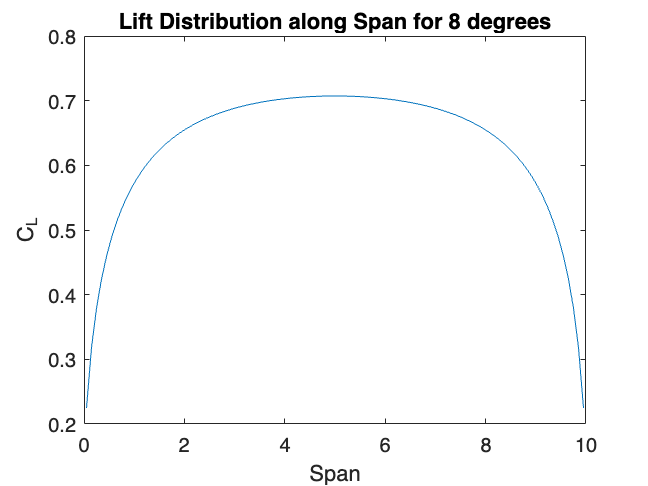


tit_1 = 'Lift Distribution along Span for';
tit_2 = num2str(aoa);
tit_comb = tit_1 + " " + tit_2 + " degrees";
plot(y_bound, Cl);
title(tit_comb);
ylabel('C_L')
xlabel('Span')

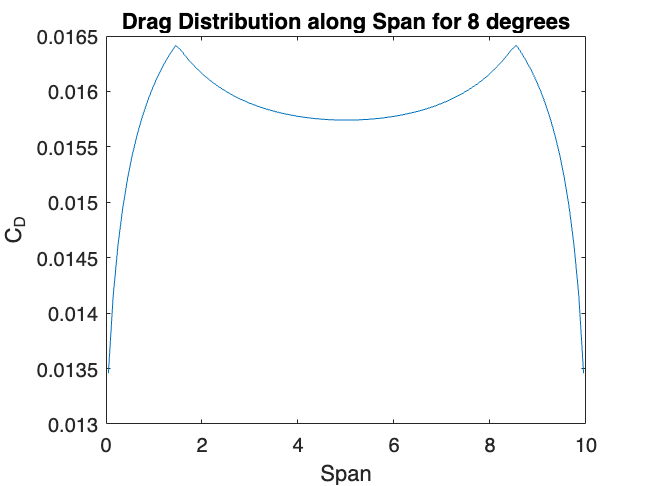


tit_1 = 'Drag Distribution along Span for';
tit_2 = num2str(aoa);
tit_comb = tit_1 + " " + tit_2 + " degrees";
plot(y_bound,Cd);
title(tit_comb);
ylabel('C_D')
xlabel('Span')

## Part 3

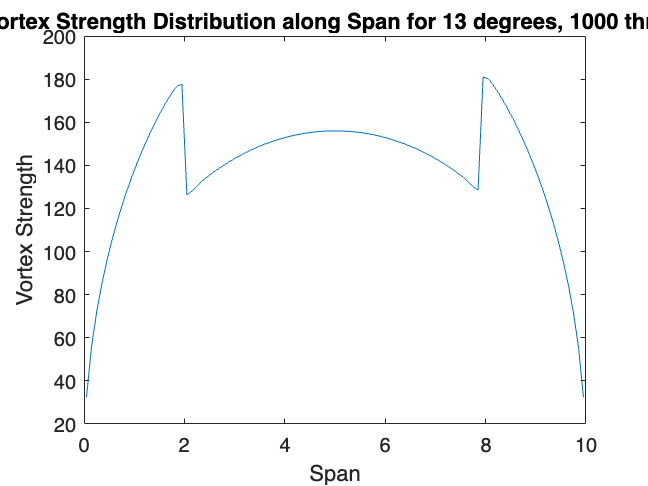

clc
clear
close all
        
% initialize parameters
thrust = 1000;
v_inf = 168.8; 
rho = 0.002;
v_h = sqrt(thrust/(2 * rho * pi * 4));
v_i = v_h * (-v_inf/(2*v_h) + sqrt((v_inf/(2*v_h))^2 + 1));
v_inf_thrust = v_inf + v_i;

c = 1.5;
b = 10;
n = 100;
k = n+1;
aoa = 13;

y_trail = zeros(k,1);
step = b/n;
for i = 1:k
    y_trail(i) = step*(i-1);
end
y_bound = y_trail(1:n)+(step/2);

alpha_g = aoa * ones(n,1);
alpha_i = zeros(n,1);
alpha_eff = alpha_g - alpha_i;

load('cl_cd.mat');
Cl = interp1(Cl_0012(:,1),Cl_0012(:,2),alpha_eff,'linear','extrap');
Cd = interp1(Cd_0012(:,1),Cd_0012(:,2),alpha_eff,'linear','extrap');

gamma_bn = 0.5 .* Cl * v_inf * c .* (sqrt(1-((y_bound - b/2)/(b/2)).^2));
gamma_bn(1:2*(n/b)) = 0.5 .* Cl(1:2*(n/b)) * v_inf_thrust * c .* (sqrt(1-((y_bound(1:2*(n/b)) - b/2)/(b/2)).^2));
gamma_bn(n-(2*(n/b)):n) = 0.5 .* Cl(n-(2*(n/b)):n) * v_inf_thrust * c .* (sqrt(1-((y_bound(n-(2*(n/b)):n) - b/2)/(b/2)).^2));
gamma_bn_new = gamma_bn + 1;

while (mean(gamma_bn)-mean(gamma_bn_new))/mean(gamma_bn) < 0.0001

    gamma_tk = zeros(k,1);
    for i = 2:n
        gamma_tk(i) = gamma_bn(i)-gamma_bn(i-1);
    end
    gamma_tk(1) = gamma_bn(1);
    gamma_tk(k) = -gamma_bn(n);

    for n=1:n
        for k=1:k
            v_ind(n,k) = -gamma_tk(k)/(4*pi*(y_bound(n)-y_trail(k)));
        end
    end
       
    v_ind_new = sum(v_ind,2);

    alpha_i = atand(-v_ind_new/v_inf);
    alpha_eff = alpha_g - alpha_i;

    Cl_0012 = [-2.025902479 -0.20812679
            0.038772741 0.00652805
            2.05982177 0.22331494
            6.017645346 0.62902511
            9.932239783 1.03258364
            14.16254093 1.30984164
            14.36464087 1.00359647
            17.98442351 0.83948681
            22.07932961 0.70332889
            26.01754869 0.85200745
            27.87918097 0.91454208
            31.99647093 1.00542989];
    
    Cl = interp1(Cl_0012(:,1),Cl_0012(:,2),alpha_eff,'linear','extrap');

    Cd_0012 = [-2.08998 0.014616
            1.992422 0.013394
            5.944141 0.016427
            10.02674 0.013064
            14.36712 0.039745
            14.96876 0.108421
            16.05107 0.145077
            18.04577 0.177656
            20.03113 0.310901
            21.982 0.347753
            26.01005 0.464323
            28.08664 0.550467
            31.939 0.688417];
    
    Cd = interp1(Cd_0012(:,1),Cd_0012(:,2),alpha_eff,'linear','extrap');
 
    gamma_bn_new = 0.5*Cl*v_inf*c;
    gamma_bn_new(1:2*(n/b)) = 0.5 .* Cl(1:2*(n/b)) * v_inf_thrust * c .* (sqrt(1-((y_bound(1:2*(n/b)) - b/2)/(b/2)).^2));
    gamma_bn_new(n-(2*(n/b)):n) = 0.5 .* Cl(n-(2*(n/b)):n) * v_inf_thrust * c .* (sqrt(1-((y_bound(n-(2*(n/b)):n) - b/2)/(b/2)).^2));
    gamma_bn = gamma_bn + 0.01*(gamma_bn_new-gamma_bn);
end

% Plot results
tit_1 = 'Vortex Strength Distribution along Span for';
tit_2 = num2str(aoa);
tit_3 = num2str(thrust);
tit_comb = tit_1 + " " + tit_2 + " degrees" + ", " + tit_3 + " thrust";
plot(y_bound, gamma_bn);
title(tit_comb);
ylabel('Vortex Strength')
xlabel('Span')

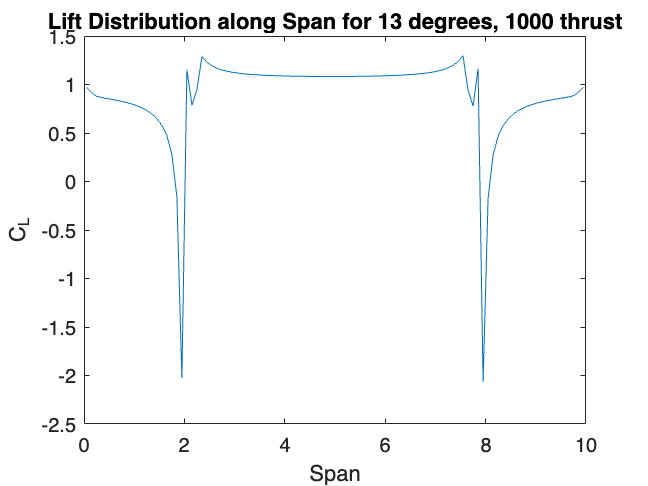


tit_1 = 'Lift Distribution along Span for';
tit_comb = tit_1 + " " + tit_2 + " degrees" + ", " + tit_3 + " thrust";
plot(y_bound, Cl);
title(tit_comb);
ylabel('C_L')
xlabel('Span')

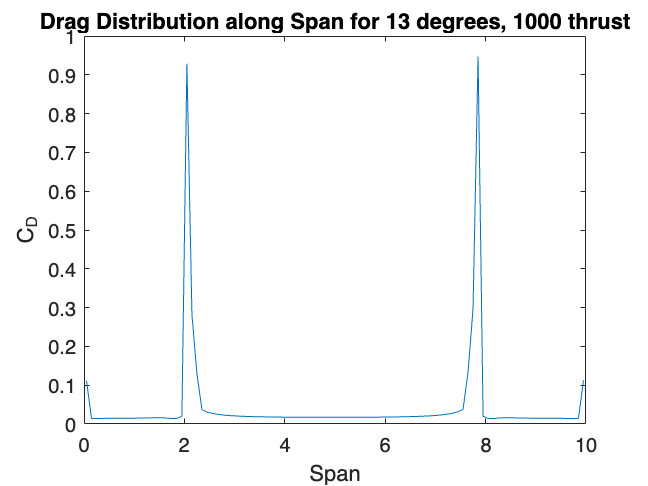


tit_1 = 'Drag Distribution along Span for';
tit_comb = tit_1 + " " + tit_2 + " degrees" + ", " + tit_3 + " thrust";
plot(y_bound, Cd);
title(tit_comb);
ylabel('C_D')
xlabel('Span')